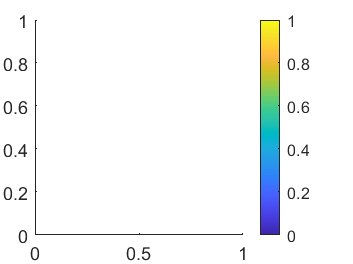

% Solar System
% 코드 typing, comment(해석 : 무엇을 나타내고자 하는지)
% 구성되어 있는 각각의 변수, 코드들에 대한 자세한 설명
% 이것을 더 개선, 발전시켜라 

clear all; clc;
[x,y,z]=sphere(19); % 19 x 19 면으로 구를 만든다. x,y,z 는 각각 20 x 20 행렬이 만들어진다.(x,y,z는 구(행성)를 만들기 위한 좌표들)
x_p=reshape(x,1,[]); % 구를 만들기 위한 20x20였던 x좌표를 1x400으로 reshape한다.
y_p=reshape(y,1,[]); % 구를 만들기 위한 20x20였던 y좌표를 1x400으로 reshape한다
z_p=reshape(z,1,[]); % 구를 만들기 위한 20x20였던 z좌표를 1x400으로 reshape한다
% reshape을 하는 이유
% 행성이 여러개이기 때문에 각각의 행성마다 x,y,z좌표를 달리하여 행성의 크기를 control할 수 있다

po_mat=[x_p;y_p;z_p;ones(size(x_p))];
% 각 행성들은 태양 주위를 공전하며 평행이동을 하는 연산을 수행하기 때문에
% 행 하나를 더 만들어주었다.

p_si_1=3; p_si_2=1; p_si_3=2;
% p_si_n는 행성n의 반지름을 증가, 감소시킬 수 있는 변수이다 (행성마다 크기가 다른 것을 구현하기 위해)

po_mat1=po_mat(1:3,:)*p_si_1; % 행성1의 반지름을 3배로 만들었다 (행성 중 가장 크다)
po_mat2=po_mat(1:3,:)*p_si_2; % 행성2의 반지름을 1배로 만들었다
po_mat3=po_mat(1:3,:)*p_si_3; % 행성3의 반지름을 2배로 만들었다
po_mat1(4,:)=1;
po_mat2(4,:)=1;
po_mat3(4,:)=1;

% colorbar();
figure(1); clf;
% caxis([0 5])으로 설정하였고 5으로 갈수록 적색농도, 0으로 갈수록 청색농도가 높다
c1=5*ones(size(z)); % 행성1의 색깔(태양). 따라서 적색이 되도록 5(* 이유)로 색깔을 정해준다
c2=3*ones(size(z)); % 행성2의 색깔. colormap jet에서 중간(3* 이유)의 색깔로 해줄 것이다
c3=1*ones(size(z)); %행성3의 색깔. 청색(1* 이유)에 가깝도록 정해줄 것이다.


psi=0; % 행성들이 자전하거나 공전하거나 좌표상에서 움직임이 있을때 필요
       % 즉 roll, pitch, yaw, surge, sway, heave 운동을 구현하기 위해 필요한 변수이다

ob_sum1=[]; ob_sum2=[]; ob_sum3=[]; 
% 행성마다 지나온 궤도를 저장하여 과거 궤도들을 출력하기 위해
% 행성마다 과거 궤도를 저장하는 변수들이다

for psi=0:2:360*3
%planet1_Sun
    %rotation
    % Rz : 행성1은 CCW yaw 운동을 한다(자전)
    % psi 속도로 자전
    Rz=[cosd(psi) -sind(psi) 0 0; 
        sind(psi) cosd(psi) 0 0;
        0 0 1 0;
        0 0 0 1];

    % Rx : 행성1은 CW pitch 운동을 한다.
    % 행성1은 x1축 기준 10도 기울어져서 자전한다 (10도 기울어진 자전)
    Rx=[cosd(10) 0 sind(10) 0;
        0 1 0 0
        -sind(10) 0 cosd(10) 0;
        0 0 0 1];

    % Rx + Rz -> 10도 기울어진 자전축 구현

    % Transition
    % 태양이 평행이동하는 궤도. 
    % 10*cosd(psi/2);10*sind(psi/2); 인 이유
    % viewpoint를 x3+방향에서 볼 때 태양은 진폭 20을 갖는 sin,cos 모양의 그래프와 같다. view([0 0 1])(그림참고)
    % viewpoint를 x1+방향에서 볼 때 태양은 반지름 10인 원 운동을 한다. view([1 0 0]); (그림참고)
    % 동시에 1/10*psi씩 x1축 방향으로 태양은 전진한다 (그림 참고)

    tran_sun=[1/10*psi;10*cosd(psi/2);10*sind(psi/2);0]

    % 바로 위의 태양의궤도를 과거의 태양궤도에 누적시킨다.
    ob_sum1=[ob_sum1;tran_sun'];

    % 태양궤도가 x1축으로 tran_sun(1)만큼, x2축으로 tran_sun(2)만큼, x3축으로 tran_sun(3)만큼
    % 이동하므로 평행이동시키기 위해 T라는 변수를 이용하였다
    T=[1 0 0 tran_sun(1);0 1 0 tran_sun(2);0 0 1 tran_sun(3);0 0 0 1];

    % 위의 Rx, Rz, T로 태양의 상태를 업데이트해준 것을 모두 합치어
    % 행성1의 상태를 동시에 업데이트 시킨다.
    y_po_mat1=T*Rx*Rz*po_mat1;

    % 20 by 20 행렬로 다시 만들어준다
    % 그 이유는 19 by 19로 만들어진 행성의 각각의 면에 색을 칠해야하기 때문에
    % 즉, surf 함수를 사용하여 각각의면에 x1,x2,x3좌표를 핸들링하여 색을 칠해줘야하기 때문에
    % reshape를 이용하여 분리해주는 작업이다
    x_re1=reshape(y_po_mat1(1,:),20,20); 
    y_re1=reshape(y_po_mat1(2,:),20,20);
    z_re1=reshape(y_po_mat1(3,:),20,20);

%planet2
    %revolution

    % 태양과 5만큼 떨어진 곳의 위치에서 원을 그리며 공전하기 위해
    % 2*psi 속도로 공전
    orbit_p2=[5*cosd(2*psi);5*sind(2*psi);0;1];

    % Rx : 행성2은 CW pitch 운동을 한다. 
    % -10도씩 기울어지며 태양 주위 공전(-10도 기울어진 공전궤도 구현)
    Rx=[cosd(-10) 0 sind(-10) 0;
        0         1 0         0;
       -sind(-10) 0 cosd(-10) 0;
        0         0 0         1];

    % 태양이 평행이동하는 것 만큼 행성2도 평행이동을 한다  
    % + 태양과 5만큼 떨어진 위치에서 원을 그리며 2*psi 속도로 공전한다
    % + 공전궤도는 -10도 기울어져 있다
    orbit_p2=Rx*orbit_p2+tran_sun;
    
    % 바로 위의 코드인 행성2의 궤도를 과거의 행성2의 궤도에 누적시킨다.
    ob_sum2=[ob_sum2;orbit_p2'];
    
    %rotation
    % Rz : 행성2은 CCW yaw 운동을 한다(자전)
    % 3*psi 속도로 자전한다
     Rz=[cosd(psi*3) -sind(psi*3) 0 0;
         sind(psi*3) cosd(psi*3) 0 0;
         0 0 1 0;
         0 0 0 1];
    % Rx : 행성2은 CW pitch 운동을 한다.
    % 행성2은 x1축 기준 -10도 기울어져서 자전한다 (-10도 기울어진 자전)
    % 위의 Rx는 orbit_p2와 곱하여 상태를 이미 업데이트해줬기 때문에 
    % 여기서 Rx변수에 새로운 값을 넣어 이용해도 괜찮다.
    Rx=[cosd(-10) 0 sind(-10) 0; 0 1 0 0; -sind(-10) 0 cosd(-10) 0;0 0 0 1];
    
    % 기존 행성2의 상태에서 
    % Rx: CW pitch운동(-10도 기울어진 자전축 자전), Rz: CCW yaw운동(3*psi속도로 자전)
    % 을 곱하여 행성2의 상태를 계속 업데이트 해준다
    y_po_mat2=Rx*Rz*po_mat2;

    % 20 by 20 행렬로 다시 만들어준다
    % 그 이유는 19 by 19로 만들어진 행성의 각각의 면에 색을 칠해야하기 때문에
    % 즉, surf 함수를 사용하여 각각의면에 x1,x2,x3좌표를 핸들링하여 색을 칠해줘야하기 때문에
    % reshape를 이용하여 분리해주는 작업이다
    x_re2=reshape(y_po_mat2(1,:),20,20)+ orbit_p2(1);
    y_re2=reshape(y_po_mat2(2,:),20,20)+ orbit_p2(2);
    z_re2=reshape(y_po_mat2(3,:),20,20)+ orbit_p2(3);

%planet3
    %revolution

    % 태양과 10만큼 떨어진 곳의 위치에서 원을 그리며 공전하기 위해
    % 3*psi 속도로 공전
    orbit_p3=[10*cosd(3*psi);10*sind(3*psi);0;1];

    % Rx : 행성3은 CW pitch 운동을 한다. 
    % 20도씩 기울어지며 태양 주위 공전(20도 기울어진 공전궤도 구현)
    Rx=[cosd(20) 0 sind(20) 0;
        0         1 0         0;
       -sind(20) 0 cosd(20) 0;
        0         0 0         1];

    % 태양이 평행이동하는 것 만큼 행성3도 평행이동을 한다  
    % + 태양과 10만큼 떨어진 위치에서 원을 그리며 3*psi 속도로 공전한다
    % + 공전궤도는 20도 기울어져 있다
    orbit_p3=Rx*orbit_p3+tran_sun;

    % 바로 위의 코드인 행성3의 궤도를 과거의 행성3의 궤도에 누적시킨다.
    ob_sum3=[ob_sum3;orbit_p3'];
    
    %rotation

    % Rz : 행성3은 CCW yaw 운동을 한다(자전)
    % 5*psi 속도로 자전한다
     Rz=[cosd(psi*5) -sind(psi*5) 0 0;
         sind(psi*5) cosd(psi*5) 0 0;
         0 0 1 0;
         0 0 0 1];
    % Rx : 행성3은 CW pitch 운동을 한다.
    % 행성3은 x1축 기준 -30도 기울어져서 자전한다 (-30도 기울어진 자전)
    % 위의 Rx는 orbit_p3와 곱하여 상태를 이미 업데이트해줬기 때문에 
    % 여기서 Rx변수에 새로운 값을 넣어 이용해도 괜찮다.
    Rx=[cosd(-30) 0 sind(-30) 0;0 1 0 0;-sind(-30) 0 cosd(-30) 0;0 0 0 1];

    % 기존 행성3의 상태에서 
    % Rx: CW pitch운동(20도 기울어진 공전궤도를 공전하는 것), Rz: CCW yaw운동(자전하는 것)
    % 을 곱하여 행성3의 상태를 계속 업데이트 해준다
    y_po_mat3=Rx*Rz*po_mat3;

    % 20 by 20 행렬로 다시 만들어준다
    % 그 이유는 19 by 19로 만들어진 행성의 각각의 면에 색을 칠해야하기 때문에
    % 즉, surf 함수를 사용하여 각각의면에 x1,x2,x3좌표를 핸들링하여 색을 칠해줘야하기 때문에
    % reshape를 이용하여 분리해주는 작업이다
    x_re3=reshape(y_po_mat3(1,:),20,20)+ orbit_p3(1);
    y_re3=reshape(y_po_mat3(2,:),20,20)+ orbit_p3(2);
    z_re3=reshape(y_po_mat3(3,:),20,20)+ orbit_p3(3);
    
    clf; view(20,20);
     ax=20; axis([ax 2*ax -ax ax -ax ax]);
    axis square; grid minor; hold on;
    xlabel('x'); ylabel('y'); zlabel('z');
    line(ob_sum1(:,1),ob_sum1(:,2),ob_sum1(:,3),'color','r') % 행성1의 누적된 궤적을 빨간선으로 그려준다
    line(ob_sum2(:,1),ob_sum2(:,2),ob_sum2(:,3),'color','g') % 행성2의 누적된 궤적을 초록색으로 그려준다
    line(ob_sum3(:,1),ob_sum3(:,2),ob_sum3(:,3),'color','b') % 행성3의 누적된 궤적을 파란색으로 그려준다
    surf(x_re1,y_re1,z_re1,c1);
    surf(x_re2,y_re2,z_re2,c2);
    surf(x_re3,y_re3,z_re3,c3);
    axis([-ax+1/10*psi ax+1/10*psi -ax ax -ax ax]);
    % x1축으로 태양을 비롯한 모든 행성들이 x1축으로  1/10*psi만큼 평행이동 하니까
    % 시간에따라 행성이 움직이는 것을 보기 위해
    % axis값을 행성1(태양)이 평행이동하는 만큼 똑같이 이동시켜 그래프 밖으로 나가지 않게 한다.

    colormap("jet"); colorbar() % colormap 함수에서 제공하는 jet라는 컬러맵이름.
    % colorbar는 현재 좌표축이나 차트의 오른쪽에 세로 컬러바를 표시합니다. 컬러바는 현재 컬러맵을 표시하고 데이터 값의 컬러맵 매핑을 나타냅니다.
    % jet colormap의 경우 cmin에 가까울수록 파란색, cmax에 가까울수록 빨간색의 농도가 짙어지는 colormap이다.
    caxis([0 5]);
    % caxis(limits)는 현재 좌표축에 대한 컬러맵 제한을 설정합니다. 
    % limits는 [cmin cmax] 형식의, 요소를 2개 가진 벡터입니다.
    % cmin보다 작거나 같은 값은 모두 컬러맵의 첫 번째 행에 매핑됩니다. 
    % cmax보다 크거나 같은 값은 모두 컬러맵의 마지막 행에 매핑됩니다.
    % cmin과 cmax 사이에 있는 모든 값은 컬러맵의 중간 행에 선형적으로 매핑됩니다.
    pause(0.000001)
end

다음 사용 중 오류가 발생함: reshape
요소 개수는 변경되어서는 안 됩니다. 해당 차원에 대한 적절한 크기를 자동으로 계산하려면 크기 입력값 중 하나로 []을 사용하십시오.